# **LEDS Project: 2026**

Synthetic identification data use 2,000 samples; classification uses 1,000 training and 600 test samples.

This Live Script is also my report. For each step, I explain what I did and why, and I briefly describe each function in the related part where it is used.


addpath('./Functions');
assert(exist('generate_demo_data','file')==2, ...
    'Open the project folder as the MATLAB current folder first.');

## Exercise 1: Estimation 

I started with (N = 2000) samples, because more data gives me more reliable results.


[u,y,Utrain,Ytrain,Utest,Ytest,demoTruth] = generate_demo_data();
N = numel(y);

#### **Step 1: Understand the model structure**

The data can come from either an AR model or an ARX model. The main difference is the input (u). In an AR model, the input does not give useful information about the output, while in an ARX model, the input has an effect on the output.

The function detectModelStructure checks this: First, it checks if the input (u) changes enough. Then, it checks the cross-correlation between (u) and (y). If the input is not constant and the cross-correlation exceeds the 99% threshold $\frac{2\ldotp 58}{\sqrt{N}}$ for at least one lag, the model is classified as ARX. Otherwise, it is classified as AR.

I use both checks because a nonconstant input alone does not show that the input is related to the output.

[modelType, info] = detectModelStructure(u,y);
fprintf('Detected model structure: %s\n', modelType);

Detected model structure: ARX


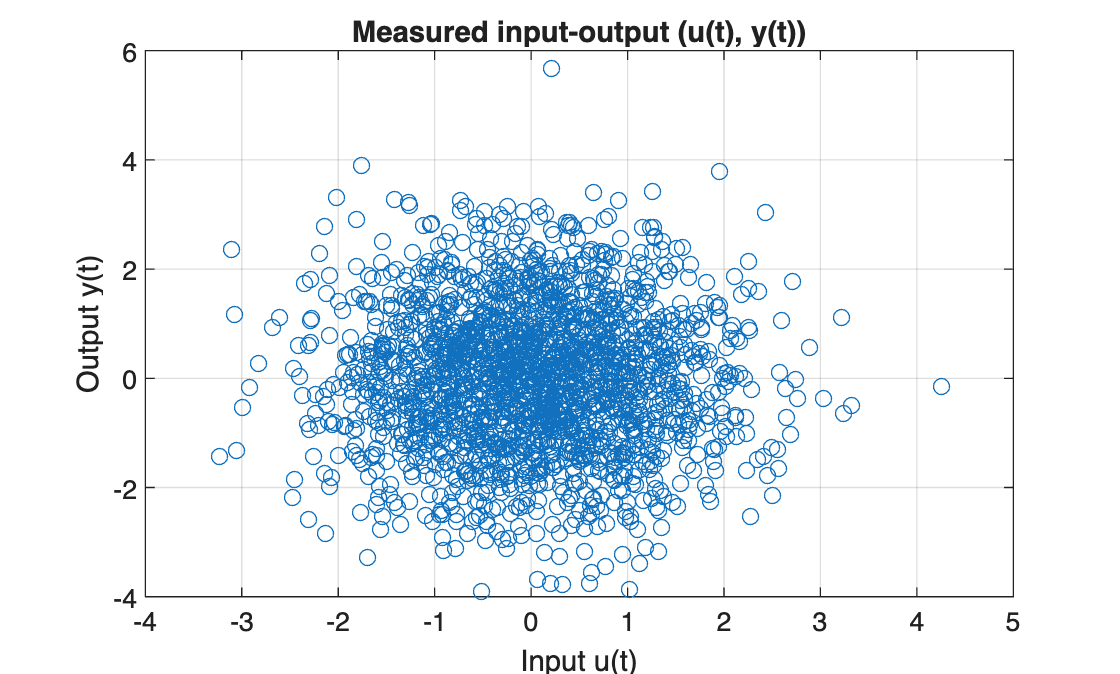

%%  plot
figure
plot(u,y,'o')
grid on
xlabel('Input u(t)')
ylabel('Output y(t)')
title('Measured input-output (u(t), y(t))')

#### **Step 2: Define the required estimation algorithm**

The assignment asks me to use the recursive version of the least-squares algorithm based on the matrix inversion lemma.

First write the model in linear-regression form y(t) = phi(t)^T theta + e(t):

- AR: 

                  $\varphi \left(t\right)$= ${\left\lbrack -y\left(t-1\right)\ldotp \ldotp \ldotp -y\left(t-n\right)\right\rbrack }^T$,  $\theta$=${\;\left\lbrack a_1 \ldotp \ldotp \ldotp a_n \right\rbrack }^T$ 

- ARX:

                  $\varphi \left(t\right)$= ${\left\lbrack -y\left(t-1\right)\ldotp \ldotp \ldotp -y\left(t-n\right)\;\;u\left(t-1\right)\ldotp \ldotp \ldotp u\left(t-n\right)\right\rbrack }^T$,

                   $\theta$=${\left\lbrack a_1 ,\ldotp \ldotp \ldotp {,a}_n \;,\;b_1 \;{,\ldotp \ldotp \ldotp ,b}_n \right\rbrack }^T$ 

Why recursive? In batch least squares, all available measurements are used together to estimate the parameters. In recursive least squares, the parameter estimate is updated when each new measurement becomes available. Using the matrix inversion lemma, the matrix P can also be updated recursively, so it is not necessary to compute a new matrix inverse at every iteration. This makes the algorithm suitable for online estimation and cheaper in computation.

**Functions: **myRegressor constructs the regression matrix. For an AR model it uses past outputs, while for an ARX model it uses both past outputs and past inputs.

myRLS  implements recursive least squares using the matrix inversion lemma. I initialize the parameter estimate with $\hat{\theta}$(0)=0, because I do not assume prior knowledge of the parameters. I use P(0)=${10}^4 \;I$to represent a large initial uncertainty.

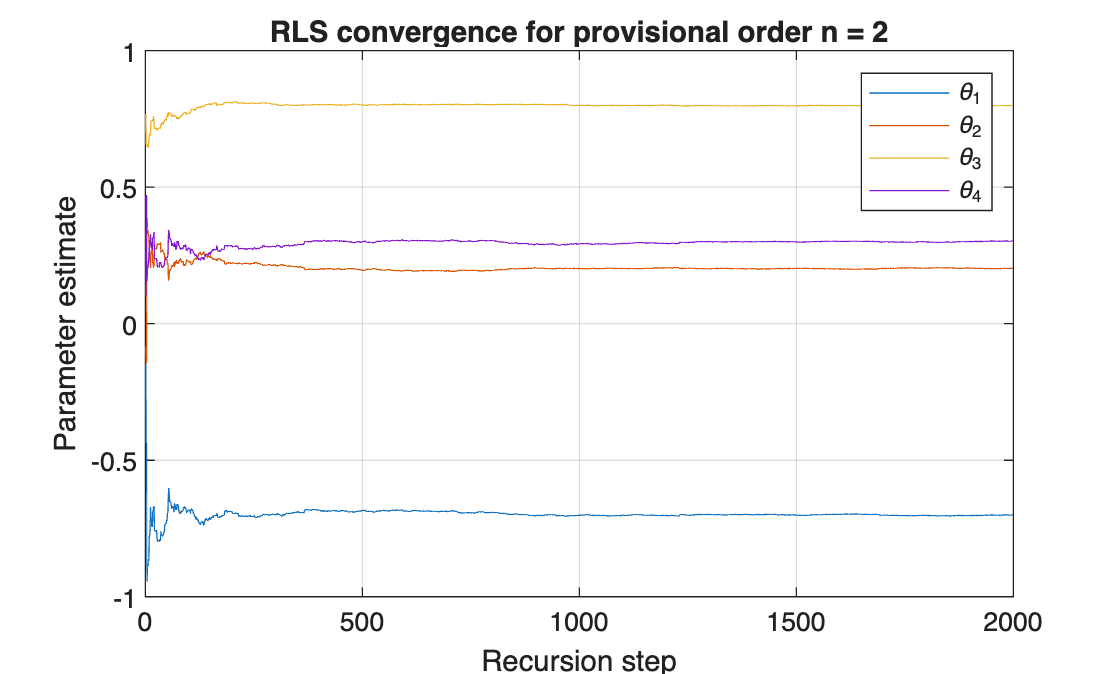

%% A Validation of the recursive estimate converges
% This is not the final selected model order.
nProv = 2;

[PhiProv,YProv] = myRegressor(u,y,nProv,modelType);

[thetaProv,thetaHistProv,residualsProv] =myRLS(PhiProv,YProv);

figure
plot(thetaHistProv.')
grid on
xlabel('Recursion step')
ylabel('Parameter estimate')
title('RLS convergence for provisional order n = 2')
legend(compose('\\theta_%d',1:size(thetaHistProv,1)), ...
       'Location','best')

Before selecting the model order, I use n=2 only as a provisional order to check the implementation of the recursive estimator. The parameter trajectories converge toward approximately constant values after the initial transient, which shows that the recursive estimation is numerically behaving as expected. The final model order is selected in the next step.

thetaProv

thetaProv =    -0.7001
    0.2022
    0.7984
    0.3034


size(PhiProv)

ans =         1998           4


size(YProv)

ans =         1998           1


For the provisional ARX model with n=2 the regression matrix has four columns corresponding to ${\left\lbrack a_{1,} {\;a}_2 \;,\;b_1 \;{,b}_2 \right\rbrack }^T$ as expected.

### **Step 3: Estimate the model order**

I don't know the model order in advance, so I estimate models for n=1,…,$n_{\max }$. For each order, I compute the residual cost J and the FPE, AIC and MDL criteria. These criteria consider both the quality of the fit and the number of estimated parameters. Therefore, increasing the model order is useful only if the improvement in the fit justifies the additional parameters.

- FPE = $J\left({\hat{\theta} }_N \right)$$\frac{N+p}{N-p}$        (Akaike Final Prediction Error)

- AIC = $N\;\textrm{logJ}\left({\hat{\theta} }_N \right)+2p$       (Akaike Information Criterion)

- MDL = $N\;\textrm{logJ}\left({\hat{\theta} }_N \right)+p\;\textrm{logN}$  (Minimum Description Length = BIC)

The function myOrder tests the model orders from 1 to `maxOrder`. I set maxOrder = 10, so I test the candidate orders from 1 to 10. For each order, the function builds the regression matrix, estimates the parameters using myRLS, and calculates the residual cost J. Then, it calculates the FPE, AIC and MDL criteria. I compare all three criteria to see how they change with the model order. In the function, nBest is selected as the order that gives the minimum MDL value.

%% Model order estimation

maxOrder = 10;

[nBest,orderTable] = myOrder(y,u,modelType,maxOrder);

fprintf('Selected order (MDL): %d\n',nBest);

Selected order (MDL): 2


disp('   n          J          FPE          AIC          MDL')

   n          J          FPE          AIC          MDL


disp(orderTable)

   1.0e+03 *

    0.0010    0.0002    0.0002   -3.1612   -3.1500
    0.0020    0.0000    0.0000   -6.4419   -6.4195
    0.0030    0.0000    0.0000   -6.4422   -6.4086
    0.0040    0.0000    0.0000   -6.4376   -6.3928
    0.0050    0.0000    0.0000   -6.4337   -6.3777
    0.0060    0.0000    0.0000   -6.4317   -6.3645
    0.0070    0.0000    0.0000   -6.4281   -6.3497
    0.0080    0.0000    0.0000   -6.4251   -6.3355
    0.0090    0.0000    0.0000   -6.4209   -6.3201
    0.0100    0.0000    0.0000   -6.4187   -6.3067



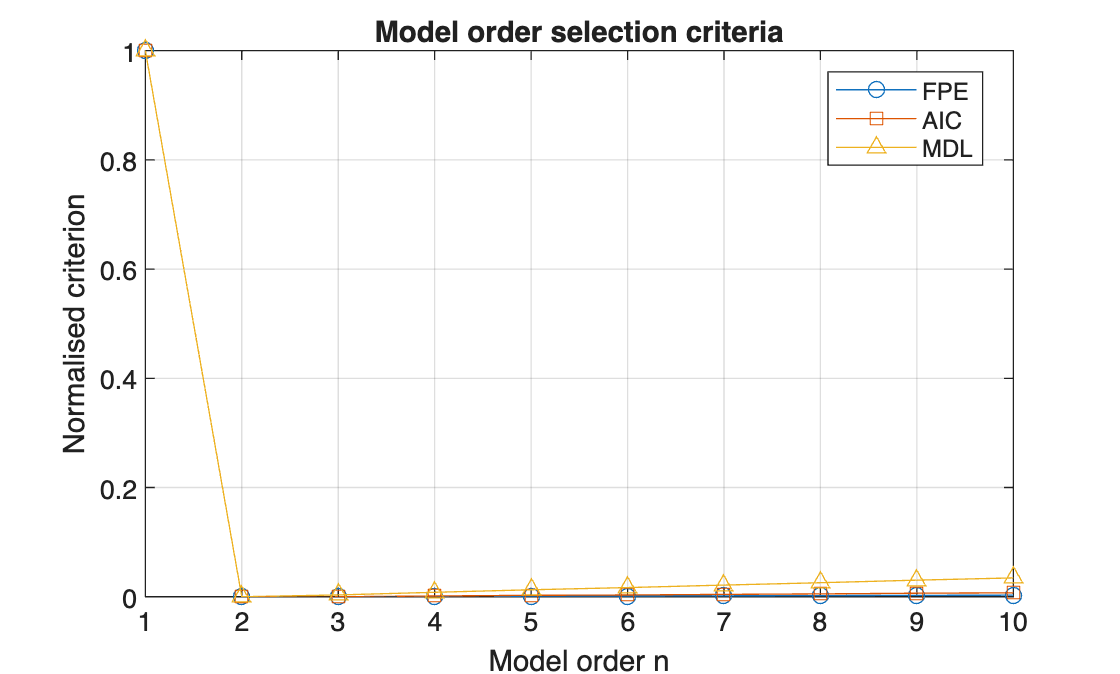

FPE = orderTable(:,3);
AIC = orderTable(:,4);
MDL = orderTable(:,5);

FPE_norm = (FPE-min(FPE))/(max(FPE)-min(FPE));
AIC_norm = (AIC-min(AIC))/(max(AIC)-min(AIC));
MDL_norm = (MDL-min(MDL))/(max(MDL)-min(MDL));

figure

plot(orderTable(:,1),FPE_norm,'-o')
hold on
plot(orderTable(:,1),AIC_norm,'-s')
plot(orderTable(:,1),MDL_norm,'-^')
grid on

xlabel('Model order n')
ylabel('Normalised criterion')
legend('FPE','AIC','MDL','Location','best')
title('Model order selection criteria')

FPE, AIC and MDL all reach their minimum at n=2. The residual cost decreases clearly from n=1 to n=2, while higher orders give only a small improvement and introduce additional parameters. Therefore, I select n=2 as the final model order. The n=2 used previously was only a provisional choice for checking the RLS implementation; here the same order is selected objectively by the model-order criteria.

%% Final model estimation

nFinal = nBest;  % fixing  the order from here
[PhiFinal,YFinal] = myRegressor(u,y,nFinal,modelType);

[thetaFinal,thetaHistFinal,residualsFinal] = ...
    myRLS(PhiFinal,YFinal);

disp('Final estimated parameters:' )

Final estimated parameters:


disp(thetaFinal)

   -0.7001
    0.2022
    0.7984
    0.3034



### **Step 4: Validate the model**

After selecting the model order and estimating the final parameters, I validate the model using the residuals. A model is good when its residuals $\varepsilon \left(t\right)=y\left(t\right)-\Phi^T$$\theta^N$ are white: if any structure were left in the residuals, the model would be missing some dynamics.For an ARX model, the residuals should also be uncorrelated with the input. 

The function myValidation checks these two conditions:   

- First, test the whiteness of the residuals using their autocorrelation. 

- Second, since my selected model is ARX, I also test the cross-correlation between the residuals and the input.

I use a significance level of $\alpha$=0.05. For the individual correlation values, the approximate 95% confidence limits are:  $\frac{\pm 1\ldotp 96}{\sqrt{N}}$ 

I also use the chi-square tests to obtain an overall statistical decision.

I use m=20 correlation lags,where m can be chosen from 5 up to $N/4$, while also considering the complexity of the model.

Since the parameters are estimated by least squares, the first n residual-input correlations can be zero by construction$\;{\widehat{r} }_{\varepsilon u} \left(\tau \right)=0$ for $\tau =1,\ldotp \ldotp \ldotp ,n$,therefore I choose $\bar{\tau} =n\;$and perform the test using the following m lags.

For this test, I also use the input autocorrelation matrix ${\sum^ˆ }_u$. The residual-input chi-square statistic is:


$$S_{\textrm{cross}} =N\frac{{{\widehat{r} }_{\varepsilon u} \left(\tau \right)}^T {{\sum^ˆ }_u }^{-1} {\widehat{r} }_{\varepsilon u} \left(\tau \right)}{{\widehat{r} }_{\varepsilon } \left(0\right)}$$


Finally, I compare the calculated statistics with their 95% chi-square thresholds. If the statistic is smaller than the corresponding threshold, I do not reject the hypothesis.

## Residual whiteness test

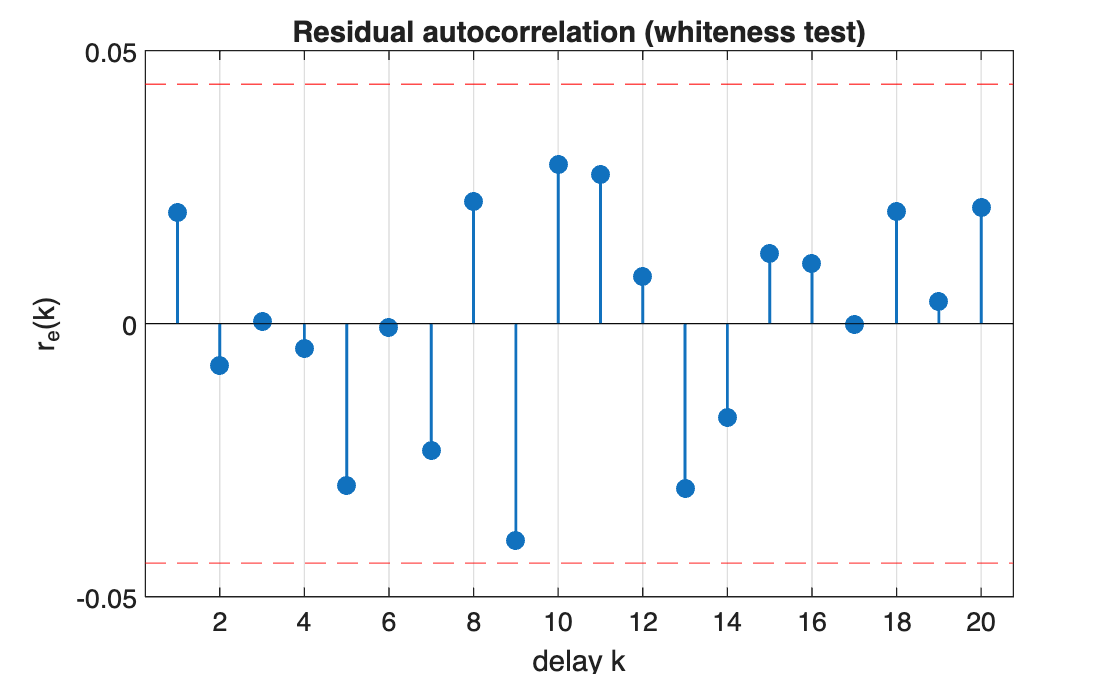

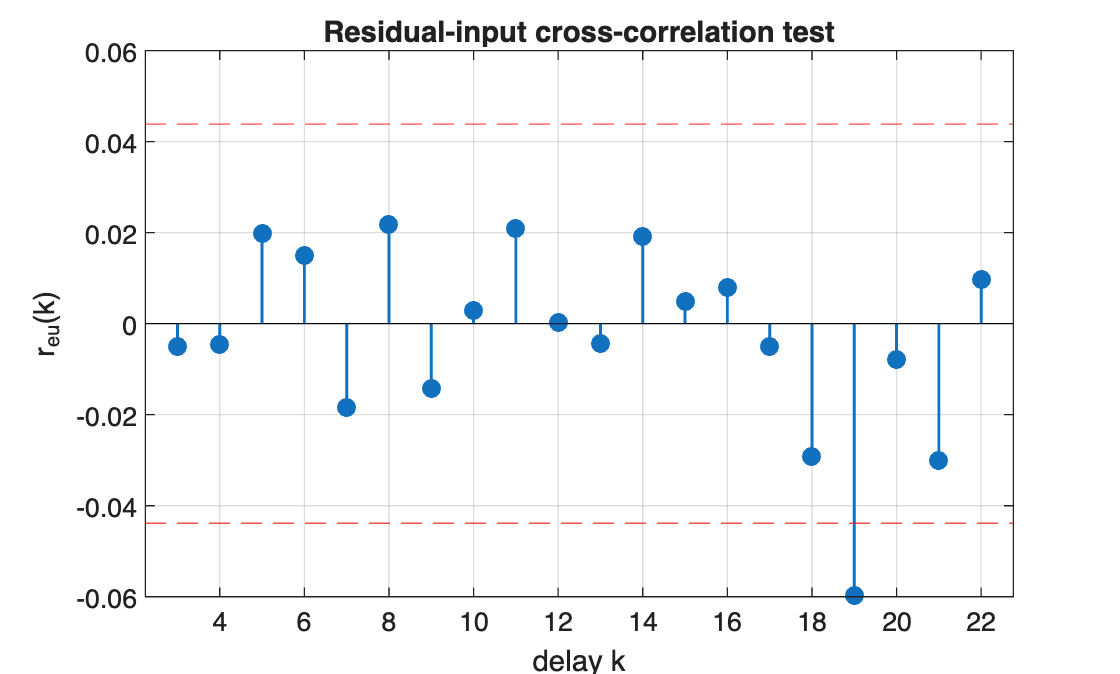

%% Model validation

val = myValidation(y,u,thetaFinal,modelType,true);


fprintf('Residual variance: %.5g\n',val.residualVar);

Residual variance: 0.039758



if val.isWhite
    fprintf('Whiteness test: S=%.2f < %.2f -> residuals WHITE, model passes validation.\n', ...
        val.S,val.threshold);
else
    fprintf('Whiteness test: S=%.2f > %.2f -> residuals NOT white, model fails validation.\n', ...
        val.S,val.threshold);
end

Whiteness test: S=16.06 < 31.41 -> residuals WHITE, model passes validation.


if strcmpi(modelType,'ARX')

    if val.isUncorrelated
        fprintf('Cross-correlation test: S=%.2f < %.2f -> residuals and input are UNCORRELATED.\n', ...
            val.Scross,val.thresholdCross);
    else
        fprintf('Cross-correlation test: S=%.2f > %.2f -> residuals and input are CORRELATED.\n', ...
            val.Scross,val.thresholdCross);
    end

end

Cross-correlation test: S=16.27 < 31.41 -> residuals and input are UNCORRELATED.


#### Results

Since the residuals pass the whiteness test and are also uncorrelated with the input, the model passes the validation tests.

# **Exercise 2: Classification**

In this exercise, I build a classifier using the labelled training set provided by generate_demo_data. First, I plot the training data to understand the shape of the two classes. Then, I choose suitable features and a classification method. Finally, I check the classifier on both the training and test sets.

%% Classification
% Utrain, Ytrain, Utest and Ytest were generated above.
% Continue with the original classification analysis below.

#### **Step 1: Understand the feature set in space**

I first plot the two training features according to their class labels. Plotting them shows whether the classes are linearly separable.

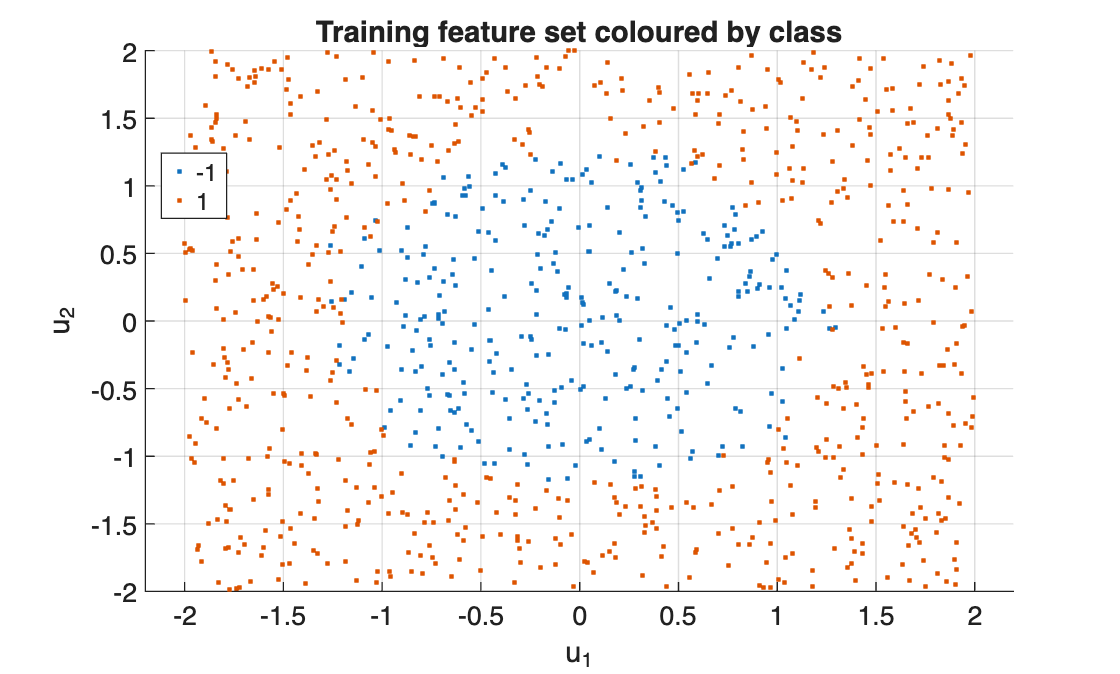

figure
gscatter(Utrain(:,1),Utrain(:,2),Ytrain)
grid on
xlabel('u_1')
ylabel('u_2')
title('Training feature set coloured by class')

The training set has two classes. From the plot, I can see that Class 1 is mainly inside an elliptical region, while Class 2 is around it. Therefore, the boundary is nonlinear, and a straight line in the original ($u_1$,$u_2$) space cannot separate the two classes.

### **Step 2: Define the required classification algorithm**

Since the boundary is curved, I add quadratic terms to the features. First, I center the data using the mean of the training set. Then, I use the new feature vector:


$$\left\lbrack x_1 ,x_2 ,x_1^2 ,x_1 x_2 ,x_2^2 \right\rbrack$$


With these new features, a linear classifier can represent a quadratic boundary in the original two-dimensional space.

%% Refined feature set

center = mean(Utrain,1);

UtrainRef = myFeatures(Utrain,center);


The function myFeatures  first centers the original features using the mean of the training set. It keeps the two centered features$x_1$ and $x_2$ and then adds the quadratic terms $x_1^2 ,x_1 x_2$ and $x_2^2$. I use the same function for the training set, test set, and decision-boundary grid.

**Classification algorithm**

I use a SVM, which is one of the classification methods studied in the course. Since I already added quadratic features to describe the curved boundary, I use a linear SVM on the new features.

%% Classification algorithm
classifier = myClassifier(UtrainRef,Ytrain);

The function myClassifier takes the refined training features and their labels and trains a linear SVM using fitcsvm. It returns the trained classifier that I use for prediction

#### Training set verification

First, I test the classifier on the training set. I compare the predicted labels with the true labels and calculate the classification error as the fraction of misclassified samples.

%% Training set verification

YpredTrain = predict(classifier,UtrainRef);

trainError = mean(YpredTrain ~= Ytrain);

fprintf('Training classification error: %.2f %%\n', ...
    100*trainError);

Training classification error: 3.30 %


The training error is 3.30%, so all the training samples are correctly classified.

#### Test set

Then, I test the classifier on the provided test set. I use the same center and the same quadratic transformation used for the training data. I do not train the classifier again; I only use the trained model to predict the test labels.

%% Test set
UtestRef = myFeatures(Utest,center);

YpredTest = predict(classifier,UtestRef);

testError = mean(YpredTest ~= Ytest);

fprintf('Test classification error: %.2f %%\n', ...
        100*testError);

Test classification error: 3.33 %


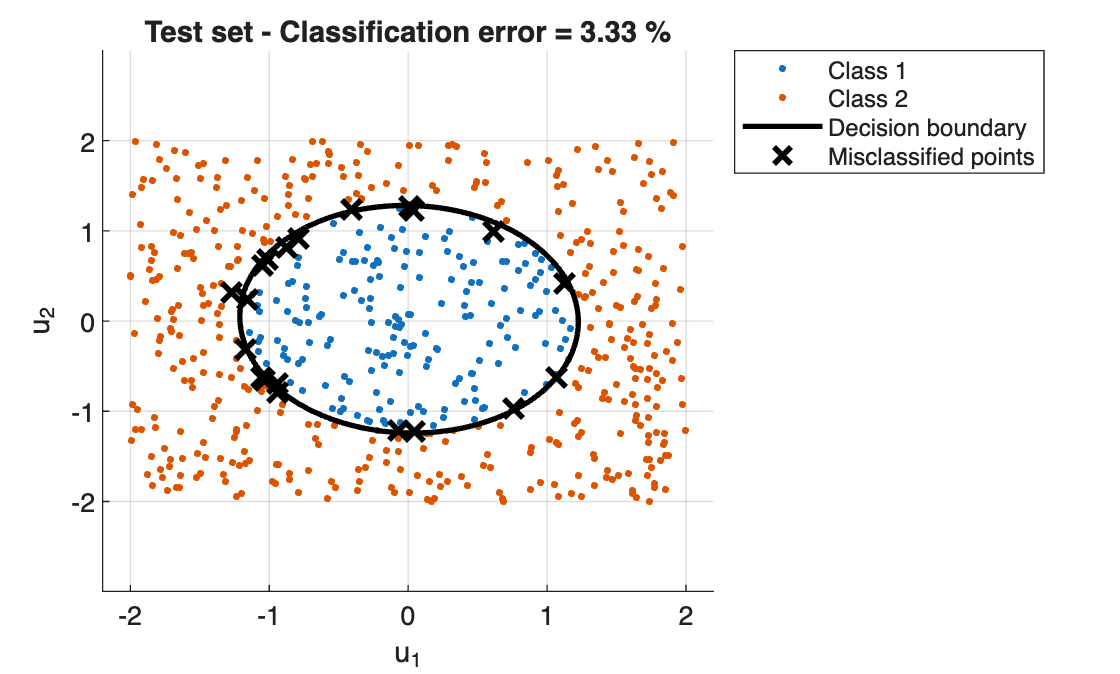

%% Test set results and decision boundary

misclassified = YpredTest ~= Ytest;

% grid in the original feature space
Uall = [Utrain; Utest];

u1 = linspace(min(Uall(:,1))-1,max(Uall(:,1))+1,200);
u2 = linspace(min(Uall(:,2))-1,max(Uall(:,2))+1,200);

[U1grid,U2grid] = meshgrid(u1,u2);

Ugrid = [U1grid(:) U2grid(:)];
UgridRef = myFeatures(Ugrid,center);

% Evaluate the classifier 
[~,scoreGrid] = predict(classifier,UgridRef);

scoreGrid = reshape(scoreGrid(:,2),size(U1grid));

% Plot
figure

gscatter(Utest(:,1),Utest(:,2),Ytest)
hold on

contour(U1grid,U2grid,scoreGrid,[0 0], ...
        'k','LineWidth',2)

plot(Utest(misclassified,1), ...
     Utest(misclassified,2), ...
     'kx','MarkerSize',10,'LineWidth',2)

grid on
xlabel('u_1')
ylabel('u_2')

title(sprintf('Test set - Classification error = %.2f %%', ...
      100*testError))

legend('Class 1','Class 2', ...
       'Decision boundary','Misclassified points', ...
       'Location','bestoutside')

hold off

**Conclusion**

The test classification error is 3.33%. The final plot shows the two test classes, the decision boundary, and the misclassified points. The wrong predictions are close to the decision boundary.

As discussed in the course, a small training error alone is not enough to evaluate a classifier. For this reason, I also use the separate test set to check how the classifier works on new data. The small test error shows that the classifier works well on this test set.